# **IO424 - Resolver Measurement**

This example shows how to set up the IO424 module for Resolver measurements. The Resolver signal is generated by the IO107 analog output module. The signal can however be generated in other ways, for example, using Resolver generators or an actual Resolver.

The IO424 is a 4-channel, 16-bit, LVDT/RVDT/Resolver/Synchro converter I/O module. This module only has read capabilities, but can generate the excitation reference signal for Resolver and LVDT/RVDT (Linear Variable Differential Transformers/Rotary Variable Differential Transformers).

## Setup

### Prerequisites

You will require at least the following to run this example:

- Speedgoat real-time target machine with one IO424 I/O module installed

- Connector cable (50-pin MDR) from the IO424 module to the terminal board

- 50-pin MDR terminal board with jumper wires

Optional:

- One [IO107 I/O module](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io107) installed

- Connector cable (68-pin SCSI) from the IO107 module to the terminal board

- 68-pin SCSI terminal board with jumper wires

### What is a Resolver

Resolvers are rotary transformers designed to measure angular displacement. They consist of a primary winding mounted on the rotor and two secondary windings mounted on the stator, oriented 90 degrees apart. An excitation signal, typically a sinusoidal waveform, is applied to the primary winding. The rotor's angular position is then determined by analyzing the amplitude and phase relationships of the signals induced in the two secondary windings.

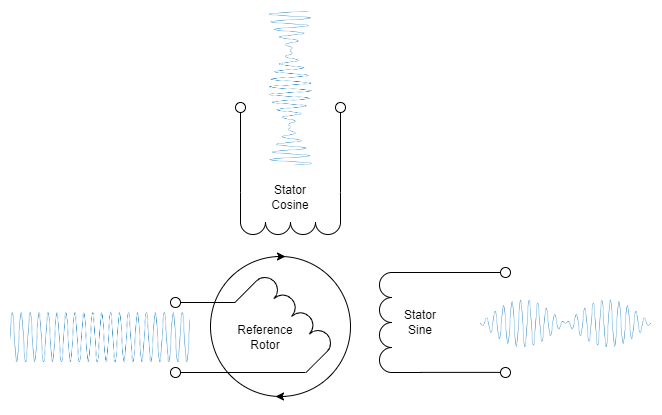

### Test Setup

Because the IO424 is designed for signal measurement, the resolver excitation signal must be provided by an external source. In this example, the IO107 module is used, leveraging its DMA capability to achieve higher sampling rates.

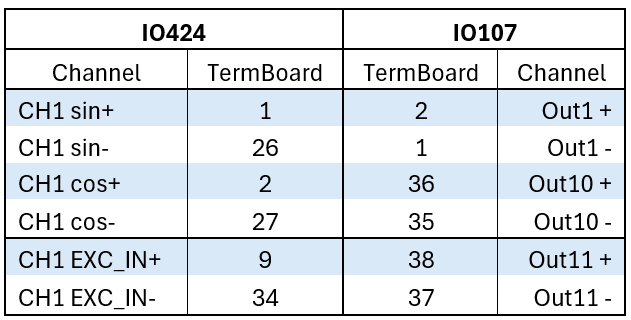

The full pin mapping of the IO424 can be found here: [IO424 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io424_pin_mapping)

## Model Description

### Resolver Signal Generation

The model's signal generation section, located on the left, uses three [Sine Wave](https://mathworks.com/help/dsp/ref/sinewave.html) blocks from the [DSP System Toolbox](https://www.mathworks.com/help/dsp/index.html) to create sampled sinusoidal signals. Each block generates a frame of 450 elements, enabling the IO107's Direct Memory Access (DMA) capability for high-speed signal output. One Sine Wave block generates a 4 VRMS, 1 kHz reference signal. This reference signal is then modulated by two lower-frequency (10 Hz) sinusoidal signals: a sine wave and a cosine wave, which serve as the modulating signals. Given that the sine and cosine waves have an amplitude of 0.5, the resulting Sin and Cos signals will have an amplitude of 2 VRMS.

If no Speedgoat analog output module is available, alternative signal generation methods can be employed. This includes using external signal generators or a separate Simulink model containing continuous Sine Wave generators. The latter allows for signal data extrapolation, which can be used to generate CSV files for external signal generators. In a real-world application, an actual resolver sensor would be used as the signal source.

### Resolver Signal Reading

The right side of the model implements the Resolver signal acquisition and processing. In the[ IO424 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io424_setup) block, the input range is configured to optimally match the generated signal levels. Status and Velocity readings are enabled, and the Position conversion is set to radians. Each channel, in this case a single channel, provides three output ports: Position, Velocity, and Status. The Position and Velocity ports each output a single numerical value, while the Status port outputs a seven-element vector, where each element corresponds to a specific error bit. For diagnostic purposes, the status bits are extracted with a [Demux block](https://mathworks.com/help/simulink/slref/demux.html), to access individual error bits.

## Open Simulink Model

 
modelName = 'sgMdl_IO424_ResolverMeasurementTest';
open_system(modelName);         % Open Simulink model

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

The figure below shows the generated signals for the first turn of the simulated Resolver.

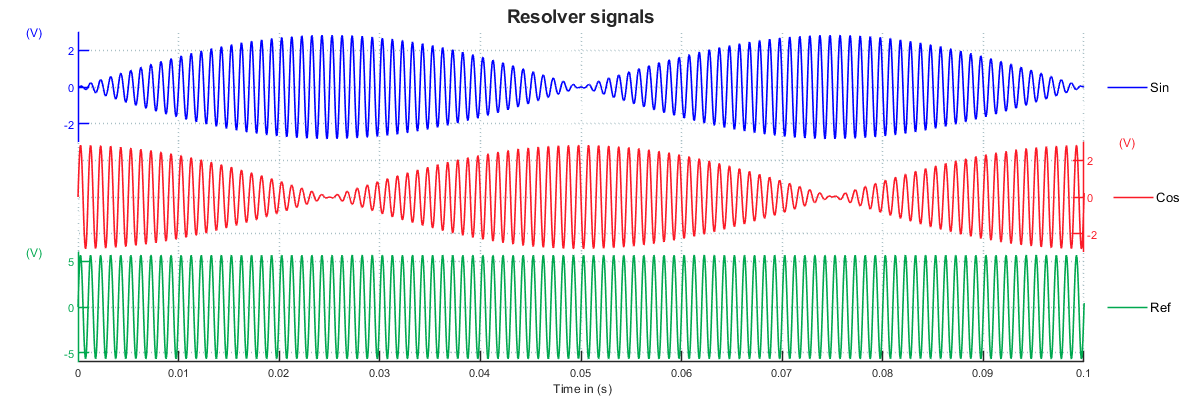

When zooming in on the generated Resolver signals, the change of phase at the node of the modulating signal (stroke position) is more apparent (0.025 s in the Cos signal).

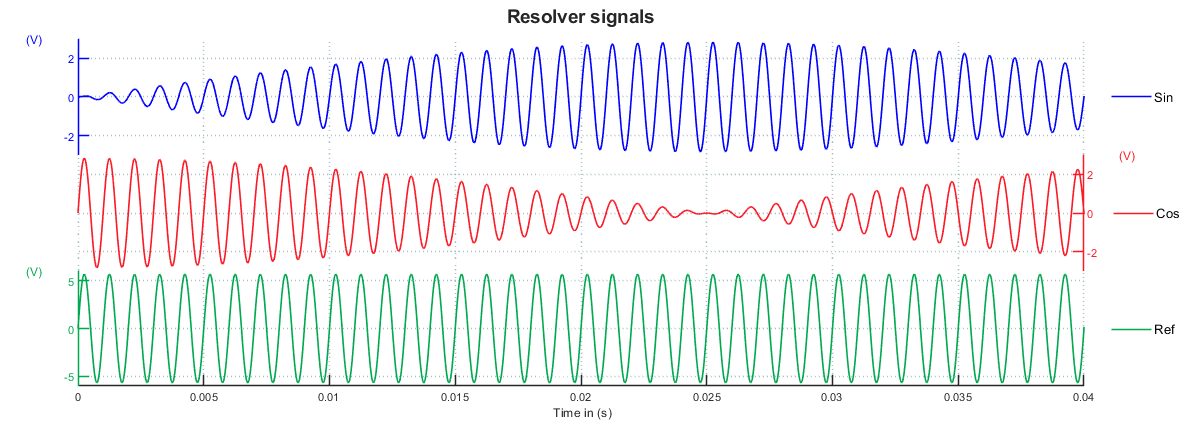

The readings align with what was configured in the Resolver signal generation. The position steadily goes from 0 rad to 2$\pi$ rad in a sawtooth wave with a period of 100 ms, so 10 Hz. The velocity also confirms the frequency. No errors were introduced in this example, so all the status bits stay at zero.

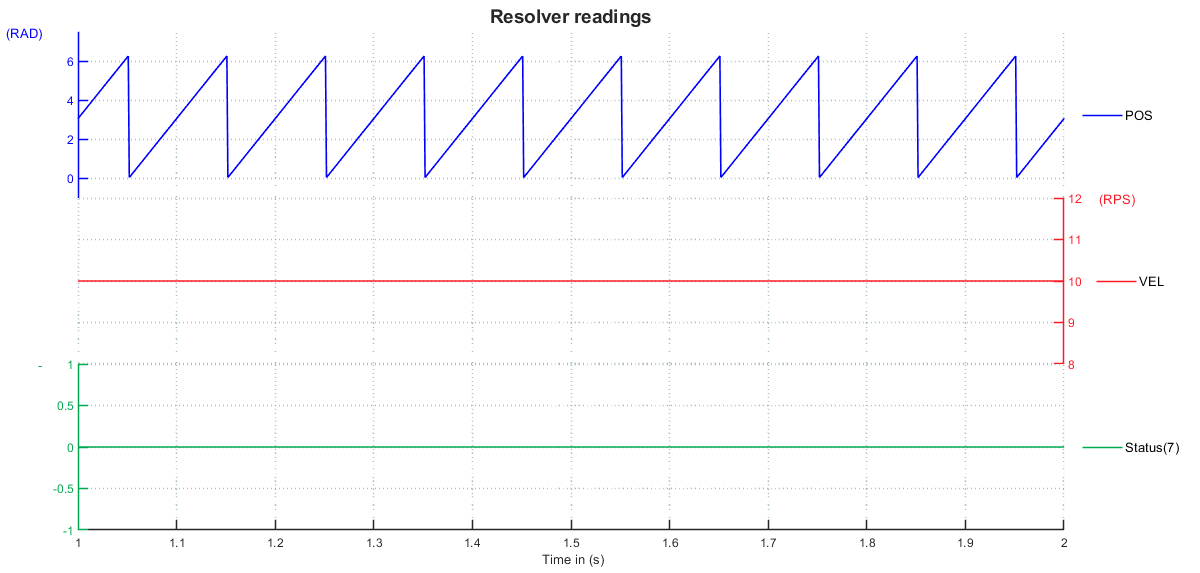

## Additional References

- [IO424 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io424)